## Dataset

### Partial dataset

The dataset is collected from a **[wind turbine specs]** 2MW wind turbine high-speed shaft driven by a 20-tooth pinion gear [1]. A **[data sampling]** vibration signal of 6 seconds was acquired each day for 50 consecutive days (there are 2 measurements on March 17, which are treated as two days in this example). An inner race fault developed and caused the failure of the bearing across the 50-day period. 

A compact version of the dataset is available in the toolbox. To use the compact dataset, copy the dataset to the current folder and enable its write permission.

% copyfile(...
%     fullfile(matlabroot, 'toolbox', 'predmaint', ...
%     'predmaintdemos', 'windTurbineHighSpeedBearingPrognosis'), ...
%     'WindTurbineHighSpeedBearingPrognosis-Data-master')
% fileattrib(fullfile('WindTurbineHighSpeedBearingPrognosis-Data-master', '*.mat'), '+w')
% copyfile(...
%     fullfile(matlabroot, 'toolbox', 'predmaint', ...
%     'predmaintdemos', 'windTurbineHighSpeedBearingPrognosis'), ...
%     'Data')
% fileattrib(fullfile('Data', '*.mat'), '+w')

The measurement time step for the compact dataset is 5 days.

timeUnit = '\times 5 day';

For the full dataset, go to this link [https://github.com/mathworks/WindTurbineHighSpeedBearingPrognosis-Data](https://github.com/mathworks/WindTurbineHighSpeedBearingPrognosis-Data), download the entire repository as a zip file and save it in the same directory as this live script. Unzip the file using this command. The measurement time step for the full dataset is 1 day.

% if exist('WindTurbineHighSpeedBearingPrognosis-Data-master.zip', 'file')
%     unzip('WindTurbineHighSpeedBearingPrognosis-Data-master.zip')
%     timeUnit = 'day';
% end
%if exist('WindTurbineHighSpeedBearingPrognosis-Data-master.zip', 'file')
 %   unzip('WindTurbineHighSpeedBearingPrognosis-Data-master.zip')
  %  timeUnit = 'day';
%end

The results in this example are generated from the full dataset. It is highly recommended to download the full dataset to run this example. Results generated from the compact dataset might not be meaningful.

## Data Import

Create a `fileEnsembleDatastore` of the wind turbine data. The data contains a **vibration signal** and a **tachometer signal**. The `fileEnsembleDatastore` will parse the file name and extract the date information as `IndependentVariables`. See the helper functions in the supporting files for more details.

% hsbearing = fileEnsembleDatastore(...
%     fullfile('.', 'WindTurbineHighSpeedBearingPrognosis-Data-master'), ...
%     '.mat');
% hsbearing.DataVariables = ["vibration", "tach"]
hsbearing = fileEnsembleDatastore(...
    fullfile('.', 'Data'), ...
    '.mat');
hsbearing.DataVariables = ["vibration", "tach"]

hsbearing =   fileEnsembleDatastore with properties:

                 ReadFcn: []
        WriteToMemberFcn: []
           DataVariables: [2×1 string]
    IndependentVariables: [0×0 string]
      ConditionVariables: [0×0 string]
       SelectedVariables: [0×0 string]
                ReadSize: 1
              NumMembers: 50
          LastMemberRead: [0×0 string]
                   Files: [50×1 string]



hsbearing.IndependentVariables = "Date"

hsbearing =   fileEnsembleDatastore with properties:

                 ReadFcn: []
        WriteToMemberFcn: []
           DataVariables: [2×1 string]
    IndependentVariables: "Date"
      ConditionVariables: [0×0 string]
       SelectedVariables: [0×0 string]
                ReadSize: 1
              NumMembers: 50
          LastMemberRead: [0×0 string]
                   Files: [50×1 string]


hsbearing.SelectedVariables = ["Date", "vibration", "tach"]

hsbearing =   fileEnsembleDatastore with properties:

                 ReadFcn: []
        WriteToMemberFcn: []
           DataVariables: [2×1 string]
    IndependentVariables: "Date"
      ConditionVariables: [0×0 string]
       SelectedVariables: [3×1 string]
                ReadSize: 1
              NumMembers: 50
          LastMemberRead: [0×0 string]
                   Files: [50×1 string]


hsbearing.ReadFcn = @helperReadData;
hsbearing.WriteToMemberFcn = @helperWriteToHSBearing;
tall(hsbearing)

ans =

  M×3 tall table

            Date                vibration             tach      
    ____________________    _________________    _______________

    07-Mar-2013 01:57:46    {585936×1 double}    {2446×1 double}
    08-Mar-2013 02:34:21    {585936×1 double}    {2411×1 double}
    09-Mar-2013 02:33:43    {585936×1 double}    {2465×1 double}
    10-Mar-2013 03:01:02    {585936×1 double}    {2461×1 double}
    11-Mar-2013 03:00:24    {585936×1 double}    {2506×1 double}
    12-Mar-2013 06:17:10    {585936×1 double}    {2447×1 double}
    13-Mar-2013 06:34:04    {585936×1 double}    {2438×1 double}
    14-Mar-2013 06:50:41    {585936×1 double}    {2390×1 double}
             :                      :                   :
             :                      :    

Sample rate of vibration signal is 97656 Hz. 

fs = 97656; % Hz

## Data Exploration

This section explores the data in both time domain and frequency domain and seeks inspiration of what features to extract for prognosis purposes.

First visualize the vibration signals in the time domain. In this dataset, there are 50 vibration signals of 6 seconds measured in 50 consecutive days. Now plot the 50 vibration signals one after each other.

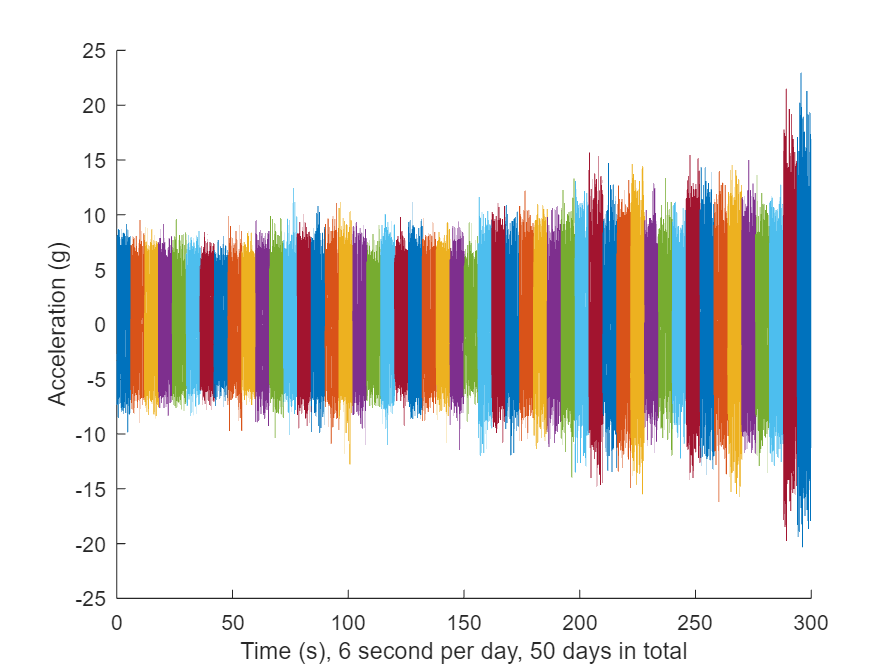

reset(hsbearing)
tstart = 0;
figure
hold on
while hasdata(hsbearing)
    data = read(hsbearing);
    v = data.vibration{1};
    t = tstart + (1:length(v))/fs;
    % Downsample the signal to reduce memory usage
    plot(t(1:10:end), v(1:10:end))
    tstart = t(end);
end
hold off
xlabel('Time (s), 6 second per day, 50 days in total')
ylabel('Acceleration (g)')

The vibration signals in time domain reveals an increasing trend of the signal impulsiveness. Indicators quantifying the impulsiveness of the signal, such as kurtosis, peak-to-peak value, crest factors *etc.*, are potential prognostic features for this wind turbine bearing dataset [2]. 

On the other hand, spectral kurtosis is considered powerful tool for wind turbine prognosis in frequency domain [3]. To visualize the spectral kurtosis changes along time, plot the spectral kurtosis values as a function of frequency and the measurement day.

hsbearing.DataVariables = ["vibration", "tach", "vib_SK", "acc_SK", "vib_SK_Mean", "vib_SK_Std", "acc_SK_Mean", "acc_SK_Std"];
colors = parula(50);
figure
hold on
reset(hsbearing)
day = 1;
while hasdata(hsbearing)
    data = read(hsbearing);
    data2add = table;
    
    % Get vibration signal and measurement date
    v = data.vibration{1};
    tach = data.tach{1};
    [speed, acceleration] = tach_deriv(tach);
    v2 = acceleration;
    
    % Compute spectral kurtosis with window size = 128
    wc = 128;
    [SK, F] = pkurtosis(v, fs, wc);
    data2add.vib_SK = {table(F, SK)};

    Mean = mean(SK);
    Std = std(SK);
    data2add.vib_SK_Mean = Mean;
    data2add.vib_SK_Std = Std;

    wc2 = 10;
    [SK, F] = pkurtosis(v2, fs, wc2);
    data2add.acc_SK = {table(F, SK)};

    Mean = mean(SK);
    Std = std(SK);
    data2add.acc_SK_Mean = Mean;
    data2add.acc_SK_Std = Std;
    
    % Plot the spectral kurtosis
    plot3(F, day*ones(size(F)), SK, 'Color', colors(day, :))
    
    % Write spectral kurtosis values
    writeToLastMemberRead(hsbearing, data2add);
    
    % Increment the number of days
    day = day + 1;
end
hold off
xlabel('Frequency (Hz)')
ylabel('Time (day)')
zlabel('Spectral Kurtosis')
grid on
view(-45, 30)
cbar = colorbar;
ylabel(cbar, 'Fault Severity (0 - healthy, 1 - faulty)')

Fault Severity indicated in colorbar is the measurement date normalized into 0 to 1 scale. It is observed that the spectral kurtosis value around 10 kHz gradually increases as the machine condition degrades. Statistical features of the spectral kurtosis, such as mean, standard deviation *etc.*, will be potential indicators of the bearing degradation [3].

## More analyisis of the signals

hsbearing.DataVariables = [hsbearing.DataVariables; "Classification"; "accel"; "vib_prop_Mean"; "vib_prop_Std"; "vib_prop_Kurtosis"; "vib_prop_Skewness"; "acc_prop_Mean"; "acc_prop_Std"; "acc_prop_Kurtosis"; "acc_prop_Skewness"];
reset(hsbearing)

%characteristics - mean, median, max, std, skewness and (kurtosis)
%variables - vibration, speed, acceleration, spectral kurtosis of former
day = 1;
while hasdata(hsbearing)
    data = read(hsbearing);
    statisticData = table;
    
    % Get vibration signal and measurement date
    v = data.vibration{1};
    
    % Compute mean and variance

    Mean = mean(v);
    Std = std(v);
    Kurtosis = kurtosis(v);
    Skewness = skewness(v);
    statisticData.vib_prop_Mean = Mean;
    statisticData.vib_prop_Std = Std;
    statisticData.vib_prop_Kurtosis = Kurtosis;
    statisticData.vib_prop_Skewness = Skewness;

    tach = data.tach{1};
    [speed, acc] = tach_deriv(tach);
    statisticData.accel = {acc};

    Mean = mean(acc);
    Std = std(acc);
    Kurtosis = kurtosis(acc);
    Skewness = skewness(acc);
    statisticData.acc_prop_Mean = Mean;
    statisticData.acc_prop_Std = Std;
    statisticData.acc_prop_Kurtosis = Kurtosis;
    statisticData.acc_prop_Skewness = Skewness;
    if day <= 26
        statisticData.Classification = categorical({'H'});
    else
        statisticData.Classification = categorical({'F'});
    end

    
    % Write spectral kurtosis values
    writeToLastMemberRead(hsbearing, statisticData);
    day = day+1;

end

## Plotting statistic features

hsbearing.SelectedVariables = ['Date'; hsbearing.DataVariables];

new_table = gather(tall(hsbearing))
results = new_table;
writetable(results);
clear results;

% acc_SK_Mean = new_table.acc_SK_Mean;
% vib_SK_Mean = new_table.vib_SK_Mean;
% 
% scatter(acc_SK_Mean(1:25), vib_SK_Mean(1:25), 'red')
% hold on
% scatter(acc_SK_Mean(26:50), vib_SK_Mean(26:50), 'blue')
% xlabel('Acceleration SK mean')
% ylabel('Vibration SK mean')
% legend('First 25 days', 'Last 25 days')
% hold off

% scatter(new_table.acc_prop_Std(1:25), new_table.vib_prop_Std(1:25), 'red')
% hold on
% scatter(new_table.acc_prop_Std(26:50), new_table.vib_prop_Std(26:50), 'blue')
% xlabel('Acceleration Std')
% ylabel('Vibration Std')
% legend('First 25 days', 'Last 25 days')
% hold off

%plot all variables agaisnt each other
% 
% hsbearing.SelectedVariables = ["Date", "vib_SK_prop", "acc_SK_prop", "vib_prop", "acc_prop"]
% new_table = gather(tall(hsbearing))
% 

% n = 12;
% values_to_plot = zeros(n, length(new_table.Date));
% for i = 1:length(new_table.Date)
%     values_to_plot(1, i) = new_table.acc_SK_prop{i}.Mean;
%     values_to_plot(2, i) = new_table.acc_SK_prop{i}.Std;
%     values_to_plot(3, i) = new_table.vib_SK_prop{i}.Mean;
%     values_to_plot(4, i) = new_table.vib_SK_prop{i}.Std;
%     values_to_plot(5, i) = new_table.acc_prop{i}.Mean;
%     values_to_plot(6, i) = new_table.acc_prop{i}.Std;
%     values_to_plot(7, i) = new_table.acc_prop{i}.Kurtosis;
%     values_to_plot(8, i) = new_table.acc_prop{i}.Skewness;
%     values_to_plot(9, i) = new_table.vib_prop{i}.Mean;
%     values_to_plot(10, i) = new_table.vib_prop{i}.Std;
%     values_to_plot(11, i) = new_table.vib_prop{i}.Kurtosis;
%     values_to_plot(12, i) = new_table.vib_prop{i}.Skewness;
% end

% p = 1;
% k = 12;
% l = length(new_table.Date);
% for i = k
%     for j = 1:12
%         subplot(4, 3, p)
%         scatter(values_to_plot(i,1:25), values_to_plot(j,1:25), 'blue')
%         hold on
%         scatter(values_to_plot(i,26:l), values_to_plot(j,26:l), 'red')
%         hold off
%         p=p+1;
%     end
% end